# Lab 4 - Controlling a Robot with EMG

In this lab you will use the Myo biointerface to "close the loop" between the human operator and the device by controlling the vMPL using EMG and/or gyroscope data. To plan out the control, you will need to identify what characteristic of the EMG signal you want to use as an input, and how to control the device.

In this lab, we will be using the Myo, the vMPL, and the MiniVIE.  If you need a refresher on how any of those applications or software works, please consult Lab 2.

## **Startup Myo Band and Interface Software**

Start up Myo Connect, MyoUdp.exe, and the MiniVIE in MATLAB as you did in Lab 2.  Don't forget to add MiniVIE to the path before starting it.  See below for reminders:

%% Set up the MiniVIE path
cd('C:\GitHub\MiniVIE');
MiniVIE.configurePath;

%% Create an object for UDP interface to the Myo Armband
hMyo = Inputs.MyoUdp.getInstance();
hMyo.initialize();

%% start up the signal viewer
hViewer = GUIs.guiSignalViewer(hMyo);

% come back to this folder
cd('C:\GitHub\hrilabs\Lab4_EMGControl');

After running the above code, make sure to set the Input Source to Thalmic Labs Myo Udp to see the signal viewer.

## **Conventional Control Channel Selection**

In a conventional control mode for surface EMG, control will be achieved using the RMS value of 100ms of the EMG signal (sampled at 1kHz) for two channels. Look at the table you made in Part 2 and select the channel with the greatest RMS value during wrist flexion and wrist extension.  (Note: Voltage values are normalized).

**Fill out the following table:**

                                            Best Channel         Resting Voltage     Activated Voltage

- Wrist Flexion                    1                                0.01                    0.55

- Wrist Extension                4                                0.01                    0.38

## **Detect Intended Motions**

In this section we will develop a script that will ‘detect’ and display the intended motion or your arm, in real-time.  Use the channels and analysis from above to select the best channels for “Wrist Flex” and “Wrist Extend”, then update a text display that will read out the current motion.  Verify that the system displays “Rest” when you are resting, “Wrist Flex” when you are actively flexing your wrist, and “Wrist Extend” when extending your wrist.

Note: In the example code below, the top portion indicates the parameter to assign channels for wrist flexion and extension, based on which channels had the greatest RMS values.  Also, set the activation thresholds above the resting voltage but below the peak voltage so the arm only moves when commanded.

**Note 2: it will probably be easier to observe the streaming classification outputs if you select the below code, right-click and select Evaluate Selection in Command Window (or select + F9).**

chIds = [1 4];             % <-- select channels for wrist flex (1) and extend (2)
wristFlexThreshold = 0.2;  % <-- adjust channel activation threshold
wristExtendThreshold = 0.08;% <-- adjust channel activation threshold

% need to shut down the viewer for this to work
if exist('hViewer', 'var') && ishandle(hViewer)
    close(hViewer);
end

StartStopForm([]); % initialize a small gui utility to control a while loop
while StartStopForm
    drawnow; % force graphic update
    
    % get the data
    emgData = hMyo.getFilteredData(100,chIds);  % get data from selected ch
    
    rmsData = rms(emgData);
    
    % apply thresholds to data to generate command
    if rmsData(1) > wristFlexThreshold       
        disp('Wrist Flex')
    elseif rmsData(2) > wristExtendThreshold   
        disp('Wrist Extend')
    else
        disp('Rest')
    end
    
end % StartStopForm while loop

## Start-up vMPL

Copy-pasted from Lab 1.  First start the vMPL (in the Applications folder under hrilabs/), then run the below code to initialize the interface.

% A udp network connection can be established to send joint
% commands to the vMPL.  The MiniVIE\Utilities\PnetClass.m 
% makes sending these messages easy.

% initialize the local ports
UdpLocalPort = 25001; % 25101 = left arm, 25001 = right arm
UdpDestinationPort = 25000; % 25100 = Left arm; 25000 = Right arm; 

% initialize the address to send to
UdpAddress = '127.0.0.1'; % IP address of the computer running vMPL

% create a PnetClass object to send commands to the arm
hArm = PnetClass(UdpLocalPort,UdpDestinationPort,UdpAddress);
hArm.initialize()

% Create a variable to store the 7 upper arm angles, in radians. 
% 1: Shoulder Flexion (+) / Shoulder Extension (-)
% 2: Shoulder Adduction (+) / Shoulder Abduction (-)
% 3: Humeral Internal Rotation (+) / Humeral External Rotation  (-) 
% 4: Elbow Flexion (+) / Elbow Extension (-)
% 5: Wrist Pronation (+) / Wrist Supination (-)
% 6: Ulnar Deviation (+) / Radial Deviation (-)
% 7: Wrist Flexion (+) / Wrist Extension (-)
upperArmAngles = zeros(1,7);

% Create a variable to store the 20 angles of the fingers, in radians
% 1: INDEX abduction/adduction
% 2: INDEX joint closest to the palm (MCP)
% 3: INDEX second joint (PIP)
% 4: INDEX furthest joint from the palm (DIP)
% 5: MIDDLE abduction/adduction
% 6: MIDDLE MCP
% 7: MIDDLE PIP
% 8: MIDDLE DIP
% 9: RING abduction/adduction
% 10: RING MCP
% 11: RING PIP
% 12: RING DIP
% 13: LITTLE abduction/adduction
% 14: LITTLE MCP
% 15: LITTLE PIP
% 16: LITTLE DIP
% 17: THUMB abduction/adduction
% 18: THUMB roll
% 19: THUMB MCP
% 20: THUMB DIP
fingerAngles = zeros(1,20);

## **Command Joint velocity and Position using EMG**

As above, change the index and threshold parameters to values based on your review of the myo signals. 

chIds = [1 4];             % <-- select channels for wrist flex (1) and extend (2)
wristFlexThreshold = 0.2;  % <-- adjust channel activation threshold
wristExtendThreshold = 0.08;% <-- adjust channel activation threshold

tLast = tic;    % store the current time for real-time control
p = 0;          % store current position
direction = 1;  % specify a direction variable +/- 1
 
StartStopForm([]); % initialize a small gui utility to control a while loop
while StartStopForm
    drawnow; % force graphic update
    
    % create a dt (delta time) variable for velocity to position
    % integration.  Using dt will keep speed constant regardless of loop
    % time
    dt = toc(tLast);
    tLast = tic;
    
    % get the data
    emgData = hMyo.getFilteredData(100,chIds);  % get data from selected ch
    % handle 2 channels
    rmsData = rms(emgData);
    
    % threshold data to generate command of certain joint velocity/direction
    if rmsData(1) > wristFlexThreshold
        v = +1.2;  % fixed negative velocity
    elseif rmsData(2) > wristExtendThreshold
        v = -1.2;  % fixed positive velocity
    else
        v = 0;
    end
 
    % perform velocity integration to get position for joints
    p = p + (v * dt);
    
    % constrain the angle to the joint limits (between ±pi/4, or ±45deg)
    p = min(max(p,-pi/4),pi/4);
    
    % set the position of the wrist
    upperArmAngles(7) = p;
    msg = typecast(single([upperArmAngles,fingerAngles]),'uint8');
    hArm.putData(msg);
    
    % print the status 
    fprintf('Channel #%d = %6.2f Channel #%d = %6.2f Wrist = %6.2f\n',...
        chIds(1), rmsData(1), chIds(2), rmsData(2),p);
end % StartStopForm while loop

## **Using Motion Based Inputs**

In this example, you will use motion sensors as additional inputs for controlling an arm.  The Myo Armband transmits its orientation (Rx, Ry, Rz), linear acceleration (Ax, Ay, Az) and angular rate (dRx, dRy, dRz) using a gyroscope.  For this strategy, we’ll use the orientation for the elbow angle directly.  For the shoulder flexion angle, we’ll use the angular rate such that jerking your arm up will raise the shoulder and rapidly extending your arm will lower the shoulder.

SHFE = 30;   % store an initial angle for the shoulder
 
StartStopForm([]); % initialize a small gui utility to control a while loop
while StartStopForm
    drawnow;
 
    hMyo.getData();                     % update myo and get data
    Rxyz = hMyo.getEulerAngles;       % get last orientation angles
    Rxyz_dot = hMyo.Gyroscope;         % get last angular rate
    
    % use the arm band angle as the elbow angle directly
    ELBOW = Rxyz(2) + 90;
 
    % For the shoulder, use the angular rate of the armband.
    % If the angular rate is fast, change the shoulder angle
    if abs(Rxyz_dot(2)) > 300
        % rotate the shoulder in proportion to angular rate
        SHFE = SHFE + 0.01*Rxyz_dot(2);
    end
    % constrain the shoulder angle to -15 < x < 180 degrees
    SHFE = min(max(SHFE,-15),180);
 
    % convert armband angles (deg) to MPL joint angles (rad)
    upperArmAngles(1) = SHFE * pi / 180;
    upperArmAngles(4) = ELBOW * pi / 180;
    
    % send the commands
    msg = typecast(single([upperArmAngles,fingerAngles]),'uint8');
    hArm.putData(msg);
    
end

## Train a Pattern Recognition Classifier

Start up the MiniVIE GUI:

cleanup;
cd('..\..\MiniVIE')
obj = MiniVIE;

After starting this up, select Thalmic Labs Myo Udp as the Input Source (make sure MyoUdp.exe is running somewhere!), select LDA Classifier under Signal Analysis. Refer to Lab 2 instructions for examples and screenshots.

Under Signal Analysis, click Select Classes, and make sure that at least the following classes are selected:

- No Movement

- Wrist Flexion

- Wrist Extension

- Spherical Grasp

- Hand Open

Finally, select MplUnity under Output Device, and **train the motions you selected**.

Once trained, save the training data file from the main MiniVIE GUI as below and note the save location (you'll need it in the next block). 

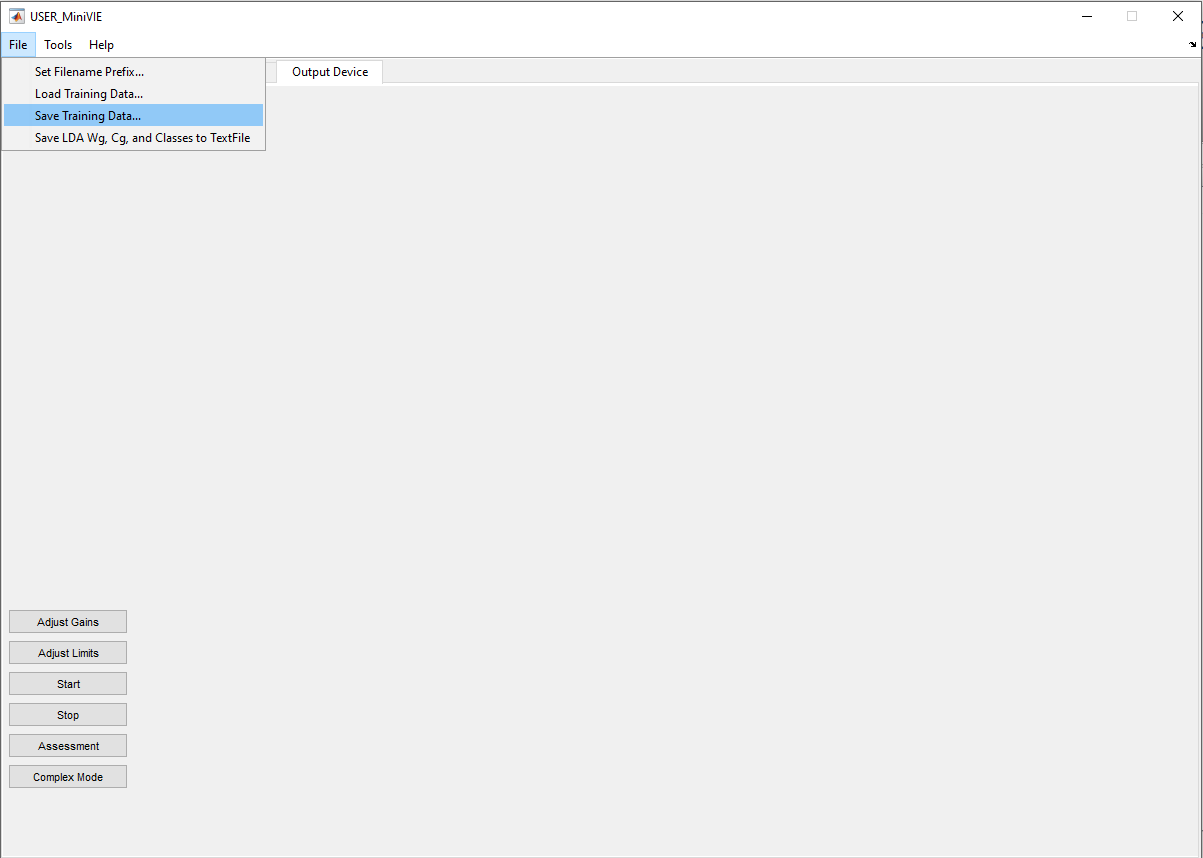

## Pattern Recognition Control

Perform pattern classification by loading training data and use a signal source and classifier object to derive intent based on the current signal state.  

**Note: it will probably be easier to observe the streaming classification outputs if you select the below code, right-click and select Evaluate Selection in Command Window (or select + F9).**

% CHANGE THIS TO MATCH YOUR TRAINING DATA FILE
myDataFilename = 'C:\GitHub\hrilabs\Lab4_EMGControl\lab4training21725.trainingData';
 
% Load training data file
hData = PatternRecognition.TrainingData();
hData.loadTrainingData(myDataFilename);
 
% Create EMG Myo Interface Object
hMyo = Inputs.MyoUdp.getInstance();
hMyo.initialize();
 
% Create LDA Classifier Object
hLda = SignalAnalysis.Lda;
hLda.initialize(hData);
hLda.train();
hLda.computeError();
 
StartStopForm([]); % initialize a small gui utility to control a while loop
while StartStopForm
        
    % Get the appropriate number of EMG samples for the 8 myo channels
    emgData = hMyo.getData(hLda.NumSamplesPerWindow,1:8);
    
    % Extract features and classify
    features2D = hLda.extractfeatures(emgData);
    [classDecision, voteDecision] = hLda.classify(reshape(features2D',[],1));
    
    % Display the resulting class number and name
    classNames = hLda.getClassNames;
    className = classNames{classDecision};
    fprintf('Class=%2d; Class = %16s;\n',classDecision,className);
    
    % refresh the display
    drawnow;
 
end

## Putting it all together

This last part of the lab is focused on combining all of the various examples/capabilities that you’ve constructed or modified up to this point, and make a fully operational motion controller for the virtual prosthetic limb.  These include: 1) the ability to send specific joint commands to the limb by first specifying a set of upper arm and hand/finger angles, and then sending a command to the virtual environment; 2) the ability to track gross arm motion and convert this motion into specific angles for the elbow and shoulder ("**Using Motion Based Inputs**" in this lab); and, 3) the ability to acquire surface EMG data and convert this data into a series of classified motions ("**Pattern Recognition Control**" in this lab).  

The goal is combine/reuse the code blocks that contain these abilities so that you can use both the inertial and surface EMG data collected from the Myoband to specify all (or most) of the joints of the limb, and then once you’ve set all the desired joint angles, then send a movement command (“hArm.putData(msg)”) to the virtual limb, all within a single function.  

Once you’ve implemented this full-arm biointerface to control the arm, copy and paste screen captures of two arm positions demonstrating full arm control through both 1) motion tracking from the inertial sensor to update shoulder and elbow positions, and 2) surface EMG signal processing to determine a class and then subsequently update wrist and hand positions.   

% put your code here
% CHANGE THIS TO MATCH YOUR TRAINING DATA FILE
myDataFilename = 'C:\GitHub\hrilabs\Lab4_EMGControl\lab4training21725.trainingData';
 
% Load training data file
hData = PatternRecognition.TrainingData();

[TrainingData] Creating Empty Training Data Object


hData.loadTrainingData(myDataFilename);

[TrainingData] Loading file: "C:\GitHub\hrilabs\Lab4_EMGControl\lab4training21725.trainingData"
[TrainingData] Loading 1498 Samples
[TrainingData] Setting window size to 250.
[TrainingData] Sample rate empty.  Assuming 1000Hz


 
chIds = [1 4];             % <-- select channels for wrist flex (1) and extend (2)
wristFlexThreshold = 0.12;  % <-- adjust channel activation threshold
wristExtendThreshold = 0.12;% <-- adjust channel activation threshold

% Create EMG Myo Interface Object
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] No file  found
[MyoUdp] UDP Comms already initialized


 
% Create LDA Classifier Object
hLda = SignalAnalysis.Lda;
hLda.initialize(hData);

[UserConfig.m] No file  found
[UserConfig.m] No file  found


hLda.train();

Training LDA with 1498 Samples (1 = 312; 2 = 271; 3 = 303; 4 = 306; 5 = 306; )
Active Channels are: [ 1 2 3 4 5 6 7 8 ]


hLda.computeError();

Percent correctly classified:   97.9 %  (1498 samples)
           Hand Open Class accuracy:	   97.1 % 	( 303 of  312)
     Spherical Grasp Class accuracy:	   95.6 % 	( 259 of  271)
    Wrist Extend Out Class accuracy:	  100.0 % 	( 303 of  303)
       Wrist Flex In Class accuracy:	   96.7 % 	( 296 of  306)
         No Movement Class accuracy:	  100.0 % 	( 306 of  306)


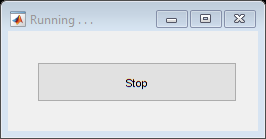

Unable to resolve the name 'hArm.putData'.

SHFE = 30;   % store an initial angle for the shoulder
upperArmAngles = zeros(1,7);
fingerAngles = zeros(1,20);
tLast = tic;    % store the current time for real-time control
p = 0;          % store current position
direction = 1;  % specify a direction variable +/- 1

StartStopForm([]); % initialize a small gui utility to control a while loop
while StartStopForm
 
    hMyo.getData();                     % update myo and get data
    Rxyz = hMyo.getEulerAngles;       % get last orientation angles
    Rxyz_dot = hMyo.Gyroscope;         % get last angular rate
    
    % use the arm band angle as the elbow angle directly
    ELBOW = Rxyz(2) + 90;
 
    % For the shoulder, use the angular rate of the armband.
    % If the angular rate is fast, change the shoulder angle
    if abs(Rxyz_dot(2)) > 300
        % rotate the shoulder in proportion to angular rate
        SHFE = SHFE + 0.01*Rxyz_dot(2);
    end
    % constrain the shoulder angle to -15 < x < 180 degrees
    SHFE = min(max(SHFE,-15),180);
 
    
    % convert armband angles (deg) to MPL joint angles (rad)
    upperArmAngles(1) = SHFE * pi / 180;
    upperArmAngles(4) = ELBOW * pi / 180;
    %fprintf('%d, %d', upperArmAngles(1), upperArmAngles(4))
    % send the commands
    %msg = typecast(single([upperArmAngles,fingerAngles]),'uint8');
    %hArm.putData(msg);
    %drawnow;


    %finger data
    dt = toc(tLast);
    tLast = tic;
    emgData = hMyo.getFilteredData(100,chIds);  % get data from selected ch
    % handle 2 channels
    rmsData = rms(emgData);
    
    % threshold data to generate command of certain joint velocity/direction
    if rmsData(1) > wristFlexThreshold
        v = +1.2;  % fixed negative velocity
    elseif rmsData(2) > wristExtendThreshold
        v = -1.2;  % fixed positive velocity
    else
        v = 0;
    end
 
    % perform velocity integration to get position for joints
    p = p + (v * dt);
    
    % constrain the angle to the joint limits (between ±pi/4, or ±45deg)
    p = min(max(p,-pi/4),pi/4);
    
    % set the position of the wrist
    upperArmAngles(7) = p;
    %fprintf('%d, %d, %d', upperArmAngles(1), upperArmAngles(4), upperArmAngles(7))
    msg = typecast(single([upperArmAngles,fingerAngles]),'uint8');
    hArm.putData(msg);
    %drawnow;
    % print the status 
    %fprintf('Channel #%d = %6.2f Channel #%d = %6.2f Wrist = %6.2f\n',...
    %    chIds(1), rmsData(1), chIds(2), rmsData(2),p);
    
    
    % Get the appropriate number of EMG samples for the 8 myo channels
    emgData = hMyo.getData(hLda.NumSamplesPerWindow,1:8);
    
    % Extract features and classify
    features2D = hLda.extractfeatures(emgData);
    [classDecision, voteDecision] = hLda.classify(reshape(features2D',[],1));
    
    % Display the resulting class number and name
    classNames = hLda.getClassNames;
    className = classNames{classDecision};
    fprintf('Class=%2d; Class = %16s;\n',classDecision,className);
    
    % refresh the display
    drawnow;
 
end

## **Submitting This Lab**

Export this *.mlx file as Lab4_##_<LastName1>_<LastName2>.pdf (## should be your computer number) and email to Lauren.Diaz@jhuapl.edu